# Part 2: Replicate the den Haan experiment, find the best-fitting parameters

%Generate/load the data
overwritefiles = true;

if ~exist('ivd','var')
    load([datadir '\ivd.mat']);
end
%cut off the comparison when growth stops
ivd.denhaan.cydat = ivd.denhaan.cydat(1:8);
ivd.denhaan.ctdat = ivd.denhaan.ctdat(1:8);
ivd.denhaan.gdw = ivd.denhaan.gdw(1:8);

if ~exist('remcfg','var')
    load('remoteconfig.mat');
end

v_default.alpha =args.p2.v.alpha;
v_default.addEnzymeToMaint = args.p2.v.addEnzymeToMaint;

v_default.initcellulose = args.p2.v.initcellulose;

if runPart2
    args.p2.v_default = v_default;
    dat2 = part2_generation(args.p2)
 
    [nrows,~] = size(dat2);
    layouts2 = dat2.layout;
    dat2.layout = cell(nrows,1);
    dat2.enzymeInMaint = repmat(args.p2.v.addEnzymeToMaint,nrows,1);
    dat2.variableInitEnzyme = repmat(args.p2.variableInitEnzyme,nrows,1);
    dat2.anaerobic = repmat(args.p2.v.anaerobic,nrows,1);
% else
%     if ~exist('dat2','var')
%         load([datadir '\dat2.mat']);
%     end
end

if runPart2_litParams
    args.p2.v.maxcycles = 1000;
    args.p2_lp = args.p2;
    args.p2_lp.model = model_default;
    dat2_litParams = table();
    alphas = -(2:.1:10);
    alphas = -(.25:.25:8);
    layouts_lp = cell(1,length(alphas));
    for i = 1:length(alphas)
        %args.p2_lp.v.alpha = pow2(alphas(i));
        args.p2_lp.v.alpha = 10^(alphas(i));
        layout_temp = part2_litParams_generation_remote(args.p2_lp);
        layouts_lp{i} = layout_temp;
    end
    [layouts_lp,remcfg] = runCometsRemotely(layouts_lp,remcfg);
% else 
%     if ~exist('dat2_litParams','var')
%         load([datadir '\dat2_litParams.mat']);
%     end
end

%finding the ideal glc uptake rate
if runPart2_vglc
    args.p2_vglc = args.p2;
    args.p2_vglc.model = model_default;
    dat2_vglc = table();
    %glcs = [1 10 20 50];
    glcs = .5:.5:10;
    layouts_glc = cell(1,length(glcs));
    for i = 1:length(glcs)
        args.p2_vglc.v.vmax_glc = glcs(i);
        args.p2_vglc.v.glcuptakerate = glcs(i);
        layout_temp = part2_litParams_generation_remote(args.p2_vglc);
        layouts_glc{i} = layout_temp;
    end
    [layouts_glc,remcfg] = runCometsRemotely(layouts_glc,remcfg);
% else 
%     if ~exist('dat2_vglc','var')
%         load([datadir '\dat2_vglc.mat']);
%     end
end
    

% %Temp 3/16/2020
% remcfg.batchnum = '200316171759';    
% 
% for i = 1:length(layouts_lp)
%     layouts_lp{i}.params.biomassLogName = 'biomass.m';
%     layouts_lp{i}.params.mediaLogName = 'media.m';
% end

if runPart2_vglc
    dat2_vglc = part2_litParams_parseRemoteResults(args.p2_vglc,layouts_glc,remcfg.batchnum);
    [nrows,~] = size(dat2_vglc);
    layouts2_vglc = dat2_vglc.layout;
    dat2_vglc.layout = cell(nrows,1);
    dat2_vglc.enzymeInMaint = repmat(args.p2.v.addEnzymeToMaint,nrows,1);
    dat2_vglc.variableInitEnzyme = repmat(args.p2.variableInitEnzyme,nrows,1);
        
else
    if runPart2_litParams
        dat2_litParams = part2_litParams_parseRemoteResults(args.p2_lp,layouts_lp,remcfg.batchnum);
        [nrows,~] = size(dat2_litParams);
        layouts2_litParams = dat2_litParams.layout;
        dat2_litParams.layout = cell(nrows,1);
        dat2_litParams.enzymeInMaint = repmat(args.p2.v.addEnzymeToMaint,nrows,1);
        dat2_litParams.variableInitEnzyme = repmat(args.p2.variableInitEnzyme,nrows,1);
        dat2_litParams.anaerobic = repmat(args.p2.v.anaerobic,nrows,1);
        dat2 = dat2_litParams;
    end
end


% %remove redundant rows from dat2
% initcel = cellfun(@(x) x(1),dat2.cellulose_amt);
% datparamcols = horzcat(dat2.km_cel,dat2.kcat_cel,dat2.alpha,dat2.vmax_glc,dat2.km_glc,initcel);
% [c,ia,ic] = unique(datparamcols,'rows');
% dat2 = dat2(ia,:);


% %retain only alphas that are multiples of x
% x = .25;
% %x = 1;
% if ~exist('dat2_full','var') || size(dat2,1) < size(dat2_full,1)
%     dat2_full = dat2; %make a backup
% end
% dat2.logalpha = log2(dat2.alpha);
% dat2.log10alpha = log10(dat2.alpha);
% % idxs = mod(dat2.logalpha,x) == 0;
% idxs = mod(dat2.log10alpha,x) == 0;
% dat2 = dat2(idxs,:);
% 
% idxs = dat2.log10alpha <= -1;
% dat2 = dat2(idxs,:);

%filter out illegal values
dat2.logalpha = log2(dat2.alpha);
dat2.log10alpha = log10(dat2.alpha);
ill = dat2.km_cel <= 0 | dat2.kcat_cel <= 0;
dat2 = dat2(~ill,:);
realas = dat2.alpha > 0;
dat2 = dat2(realas,:);

%Plots for variable glc uptake rate
if exist('dat2_vglc','var')
[nrows,~] = size(dat2_vglc);
figure();
hold on;
for i = 1:nrows
    plot(dat2_vglc.t{i},dat2_vglc.biomass{i},'LineWidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--','LineWidth',2);
hold off;
leg = legend([num2str(dat2_vglc.vmax_glc);'Ex'],'location','best');
title(leg,'Glc Uptake Vmax');
title('Effect of Variable Glucose Uptake');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
figure();
hold on;
for i = 1:nrows
    plot(dat2_vglc.t{i},dat2_vglc.glc_amt{i},'LineWidth',2);
end
hold off;
leg = legend([num2str(dat2_vglc.vmax_glc)],'location','best');
title(leg,'Glc Uptake Vmax');
title('Effect of Variable Glucose Uptake');
xlabel('Time (h)');
ylabel('Glc (mmol)');
set(gca,'YScale','log');
end

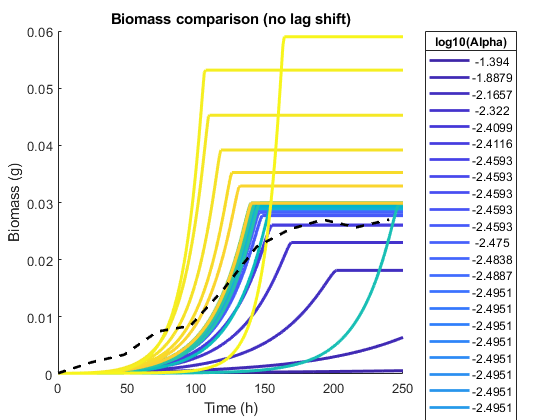

%plot growth for all alphas
dat2 = sortrows(dat2,'alpha','descend');
%dat2 = dat2(ismember(dat2.alpha, pow2([-8 -7 -6 -5 -5.4 -4 -3 -2])),:);
alphas_log10 = dat2.log10alpha;
alphas = dat2.alpha;
colors = parula(1 + length(dat2.alpha));
figure();
% linestyles = {'-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' ...
%     '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
%     '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
%     '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
%     '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'...
%     '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-' '-'};
maxtime = 250;
xmax = 250;
xmax = 1000;
hold on;
for i = 1:length(alphas_log10)
    r = dat2(i,:);
    tmax = find(r.t{1} >= xmax,1);
    plot(r.t{1}(1:tmax),r.biomass{1}(1:tmax),'color',colors(i,:),'lineWidth',2);
end
%title('Biomass');
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
expphrase = 'Exp.          ';
xlim([0,maxtime]);
[~,nchars] = size(num2str(alphas_log10));
expphrase = expphrase(1:nchars);
leg = legend([num2str(alphas_log10);expphrase],'location','eastoutside');
title(leg,'log10(Alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
title('Biomass comparison (no lag shift)');

hold off;

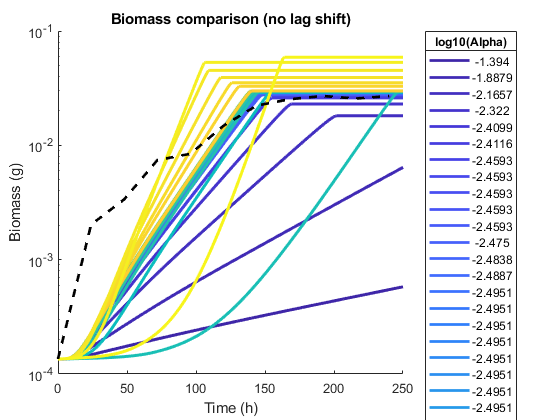


f = figure();
hold on;
[nrows,ncols] = size(dat2);
for i = 1:nrows
    r = dat2(i,:);
    plot(r.t{1}(1:tmax),r.biomass{1}(1:tmax),'color',colors(i,:),'lineWidth',2);
    
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
leg = legend([num2str(alphas_log10);expphrase],'location','eastoutside');
title(leg,'log10(Alpha)');
xlim([0,maxtime]);
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
hold off;

title('Biomass comparison (no lag shift)');


if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_noshift.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_noshift.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_noshift.eps');%for LaTeX
end


% %surf plot of the above
% %%Doesn't work with the hill-climbing method
% t = dat2.t{1};
% [X,Y] = meshgrid(alphas,t);
% z = zeros(length(alphas),length(t));
% for i = 1:length(alphas)
%     for j = 1:length(t)
%         rownum = dat2.alpha==pow2(alphas(i));
%         z(i,j) = dat2.biomass{rownum}(j);
%     end
% end
% surf(X,Y,z');
% xlabel('log2(alpha)');
% ylabel('Time (h)');
% zlabel('Biomass(g)');
% shading interp;
% 
% view([47.100 31.200])

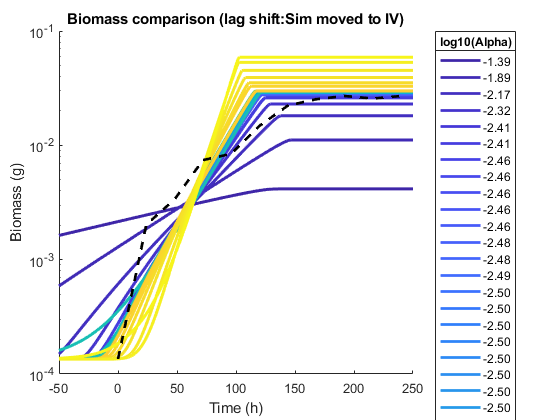



%plot the series adjusted for lag phases
%Version 1: move the sim data

if ~isfield(dat2,'shift_hours')
    steplength = dat2.t{1}(2);
    dat2.shift_hours = dat2.shift * steplength;
end
f = figure();
hold on;
[nrows,ncols] = size(dat2);
colors = parula(1 + nrows);
for i = 1:nrows
    r = dat2(i,:);
    steplength = r.t{1}(2);
    t_extend = [(-xmax:steplength:-1)'; r.t{1}];
    t_shifted = t_extend + r.shift_hours;
    bio_extend = [repmat(r.biomass{1}(1),length(t_extend) - length(r.t{1}),1); r.biomass{1}];
    %startpos = find(t_shifted == 0);
    %endpos = find(t_shifted == xmax);
    %plot(t_shifted(startpos:endpos),bio_extend(startpos:endpos),'color',colors(i,:),'lineWidth',2);
    plot(t_shifted,bio_extend,'color',colors(i,:),'lineWidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
alphas_log10 = dat2.log10alpha;
expphrase = 'Exp.       ';
alphaphrases = num2str(round(alphas_log10,3),'%1.2f');
[~,phrasesize] = size(alphaphrases);
expphrase = expphrase(1:phrasesize);
leg = legend([alphaphrases;expphrase],'location','eastoutside');
title(leg,'log10(Alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
xlim([-50,maxtime]);

title('Biomass comparison (lag shift:Sim moved to IV)');
hold off;

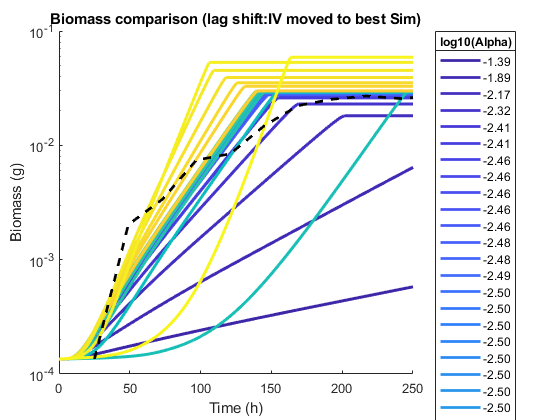


if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_shift.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_shift.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\compare_invivo_shift.eps');%for LaTeX
end

%Version 2: move the experimental data to sit on the best fit
f = figure();
hold on;
[nrows,ncols] = size(dat2);
for i = 1:nrows
    r = dat2(i,:);
    plot(r.t{1}(1:tmax),r.biomass{1}(1:tmax),'color',colors(i,:),'lineWidth',2);
end
bestshift = dat2.shift_hours(dat2.rmse == min(dat2.rmse));
ctdat_shifted = ivd.denhaan.ctdat - bestshift(1);
plot(ctdat_shifted,ivd.denhaan.gdw,'--k','linewidth',2);
leg = legend([alphaphrases;expphrase],'location','eastoutside');
title(leg,'log10(Alpha)');
xlim([0,maxtime]);
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');

title('Biomass comparison (lag shift:IV moved to best Sim)');
hold off;

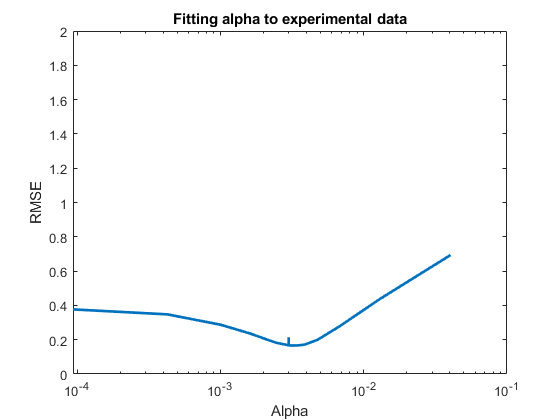

plot(dat2.alpha,dat2.rmse,'linewidth',2);
set(gca,'xscale','log')
title('Fitting alpha to experimental data');
ylabel('RMSE');
xlabel('Alpha');
ylim([0,2]);

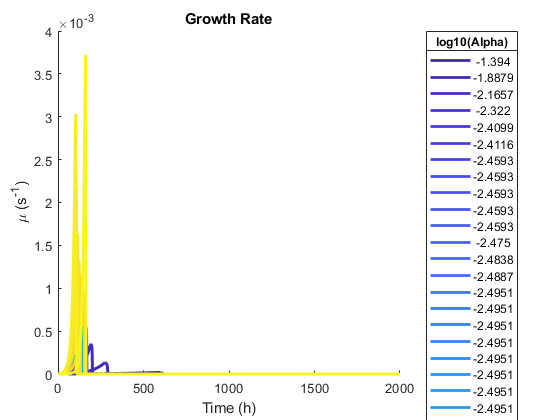


figure();
hold on;
for i = 1:length(alphas_log10)
    r = dat2(alphas_log10(i) == alphas_log10,:);
    timestep = r.t{1}(2);
    plot(r.t{1}(1:end-1),r.biomass_delta{1}/timestep,'color',colors(i,:),'lineWidth',2);
end
title('Growth Rate');
xlabel('Time (h)');
ylabel('\mu (s^-^1)');
% leg = legend(num2str(log2(alphas)),'location','eastoutside');
% title(leg,'log2(Alpha)');
leg = legend(num2str(alphas_log10),'location','eastoutside');
title(leg,'log10(Alpha)');
hold off;

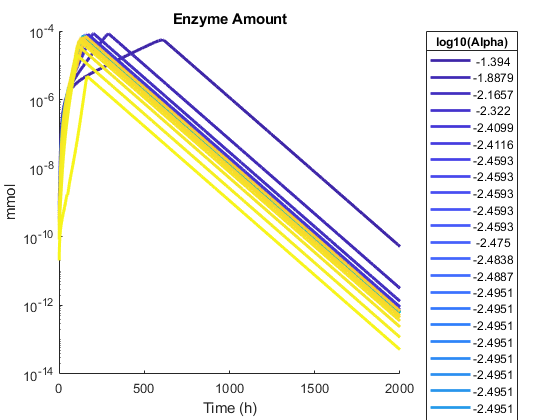


figure();
hold on;
for i = 1:length(alphas_log10)
    r = dat2(alphas_log10(i) == alphas_log10,:);
    plot(r.t{1},r.enzyme_amt{1},'color',colors(i,:),'lineWidth',2);
end
title('Enzyme Amount');
ylabel('mmol');
xlabel('Time (h)');
% leg = legend(num2str(log2(alphas)),'location','eastoutside');
% title(leg,'log2(Alpha)');
leg = legend(num2str(alphas_log10),'location','eastoutside');
title(leg,'log10(Alpha)');
set(gca,'yscale','log');
hold off;


% figure();
% hold on;
% for i = [2 3 4 5 6 7 8]
%     r = dat2(dat2.alpha == pow2(-i),:);
%     idx = find(i == [2 3 4 5 6 7 8]);
%     plot(r.t{1}(1:end-1),r.biomass_delta{1}./(r.biomass{1}(1:end-1) * r.layout{1}.params.timeStep),linestyles{idx},'color',colors(idx,:),'lineWidth',2);
% end
% title('Growth Rate (s^-^1)');
% leg = legend(num2str([-2; -3; -4; -5; -6; -7; -8]),'location','eastoutside');
% title(leg,'log2(Alpha)');
% hold off;

% %Find the fits
rmse = dat2.rmse;
% rs = zeros(length(alphas),1);
% ssrs = zeros(length(alphas),1);
% 
% for i = 1:length(alphas)
%     row = dat2(i,:);
%     t_end = find(row.t{1} >= 250,1);
%     bio = row.biomass{1}(1:t_end);
%     t = row.t{1}(1:t_end);
%     y_calc = bio\t;
%     [pf,S] = polyfit(t,bio,3);
%     [y_fit,delta] = polyval(pf,ivd.denhaan.ctdat,S);
% %     hold on;
% %     plot(t,bio,t,y_fit);
% %     plot(t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--');
% %     hold off;
%     gdw = ivd.denhaan.gdw;
%     res = ivd.denhaan.gdw - polyval(pf,ivd.denhaan.ctdat);
%     %plot(res)
%     r2 = 1 - sum((gdw - y_fit).^2)/sum((gdw - mean(y_fit)).^2);
%     rs(i) = r2;
%     ssrs(i) = sum((gdw - y_fit).^2);
%     
% end
% 
% rss_fun3_n = zeros(length(alphas),1);
% rss_fun4_n = zeros(length(alphas),1);
% rss_fun3_l = zeros(length(alphas),1);
% rss_fun4_l = zeros(length(alphas),1);
% r2_3_n = zeros(length(alphas),1);
% r2_4_n = zeros(length(alphas),1);
% r2_3_l = zeros(length(alphas),1);
% r2_4_l = zeros(length(alphas),1);
% v3n = zeros(length(alphas),1);
% v4n = zeros(length(alphas),1);
% v3l = zeros(length(alphas),1);
% v4l = zeros(length(alphas),1);
% k3n = zeros(length(alphas),1);
% k4n = zeros(length(alphas),1);
% k3l = zeros(length(alphas),1);
% k4l = zeros(length(alphas),1);
% rmse3n = zeros(length(alphas),1);
% rmse4n = zeros(length(alphas),1);
% rmse3l = zeros(length(alphas),1);
% rmse4l = zeros(length(alphas),1);
% rmse = zeros(length(alphas),1); %raw RMSE without a regression line
% for i = 1:length(alphas)
%     t_exp = ivd.denhaan.ctdat;
%     b_exp = ivd.denhaan.gdw;
%     t_sim = dat2.t{i};
%     b_sim = dat2.biomass{i};
%     b_sim = b_sim(ismember(t_sim,t_exp));
%     logbexp = log10(b_exp);
%     logbsim = log10(b_sim);
%     summation = 0;
%     n = length(logbexp);
%     for j = 1:n
%         val = logbsim(j) - logbexp(j);
%         val = val^2;
%         summation = summation + val;
%     end
%     rmse(i) = sqrt(summation/n);
% end
% for i = 1:length(alphas)
%     [rss_fun3_n(i),r2_3_n(i),v3n(i),k3n(i),rmse3n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},3);
%     [rss_fun4_n(i),r2_4_n(i),v4n(i),k4n(i),rmse4n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},4);
%     [rss_fun3_l(i),r2_3_l(i),v3l(i),k3l(i),rmse3l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},3,'log10');
%     [rss_fun4_l(i),r2_4_l(i),v4l(i),k4l(i),rmse4l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2.t{i},dat2.biomass{i},4,'log10');
% end
% 
% km = dat2.km_cel;
% kcat = dat2.kcat_cel;
% r2_3_n = abs(r2_3_n);
% r2_4_n = abs(r2_4_n);
% r2_3_l = abs(r2_3_l);
% r2_4_l = abs(r2_4_l);
% dat2.r2 = r2_3_l;
% dat2.rmse_3_log = rmse3l;
% dat2.rmse_4_log = rmse4l;
% dat2.rmse_3 = rmse3n;
% dat2.rmse_4 = rmse4n;
% dat2.rmse = rmse;
% fittab = table(alphas,rmse,rss_fun3_n,rss_fun4_n,rss_fun3_l,rss_fun4_l,r2_3_n,r2_4_n,r2_3_l,r2_4_l,v3n,v4n,v3l,v4l,k3n,k4n,k3l,k4l,rs,ssrs,km,kcat)
% best = alphas(ssrs==min(ssrs))
% best = alphas(r2_3_l==min(r2_3_l))
% best = alphas(rmse == min(rmse))
% best_arr = alphas([find((rss_fun3_n==min(rss_fun3_n))) find((rss_fun4_n==min(rss_fun4_n))) find((rss_fun3_l==min(rss_fun3_l))) find((rss_fun4_l==min(rss_fun4_l)))...
%     find((r2_3_n==min(r2_3_n))) find(r2_4_n==min(r2_4_n)) find(r2_3_l==min(r2_3_l)) find(r2_4_l==min(r2_4_l)) ])
% plotdata = horzcat(ssrs/max(ssrs),rss_fun3_n/max(rss_fun3_n),rss_fun4_n/max(rss_fun4_n),rss_fun3_l/max(rss_fun3_l)...
%     ,rss_fun4_l/max(rss_fun4_l),r2_3_n/max(r2_3_n),r2_4_n/max(r2_4_n),r2_3_l/max(r2_3_l),r2_4_l/max(r2_4_l),...
%     k3n/max(k3n),k4n/max(k4n),k3l/max(k3l),k4l/max(k4l),rmse/max(rmse));
% plot(alphas,plotdata);
% legend({'ssrs','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','k3n','k4n','k3l','k4l','rmse'},'location','west');
% plotdata = horzcat(rmse3n/max(rmse3n),rmse4n/max(rmse4n),rmse3l/max(rmse3l),rmse4l/max(rmse4l),rmse/max(rmse));
% plot(alphas,plotdata);
% legend({'rmse3n' 'rmse4n' 'rmse3l' 'rmse4l' 'rmse'})

%Analysis for a single alpha
data = ivd.denhaan;
%best = alphas(find(rmse3l == min(rmse3l)))
best = dat2.alpha(find(rmse==min(rmse)))

best = 0.0032

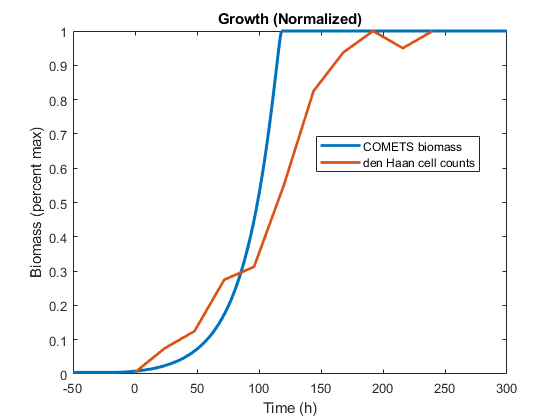

a = pow2(best);
row = dat2(rmse==min(rmse),:);
if size(row,1) > 1
    disp('Warning! Multiple entries have RMSE equal to the minimum!');
    minrmse.rows = row;
    minrmse.a = a;
    minrmse.best = best;
    best = best(1);
    a = a(1);
    row = row(1,:);
end
%v = row.layout{1}.models{1}.v;
% % [pf,S] = polyfit(row.t{1},row.biomass{1},3);
% % 
% % plot(row.t{1},row.biomass{1}/max(row.biomass{1}),data.ctdat,data.cydat/max(data.cydat),row.t{1},polyval(pf,row.t{1},S)/max(polyval(pf,row.t{1},S)),'lineWidth', 2)
% % leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
% % title('Growth (Normalized)')
% % xlabel('Time (h)')
% % ylabel('Biomass (percent max)')
% % 
% % 
% % %Denhaan biomass extrapolated from cell counts & max observed biomass reported as .27 g/L
% % %plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,row.t{1},polyval(pf,row.t{1},S),'lineWidth', 2)
% % %leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
% % plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,'lineWidth', 2)
% % leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
% % %title('Growth')
% % xlabel('Time (h)')
% % ylabel('Biomass (g)')
% % 
% % plot(row.t{1},log10(row.biomass{1}),data.ctdat,log10(data.gdw),row.t{1},log10(polyval(pf,row.t{1},S)),'lineWidth', 2)
% % leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
% % title('Growth')
% % xlabel('Time (h)')
% % ylabel('Log10(Biomass) (g)')

xmin = -50;
xmax = 300;

t_extend = [(-xmax:-1)'; row.t{1}];
t_shifted = t_extend + row.shift_hours;
bio_extend = [repmat(row.biomass{1}(1),xmax,1); row.biomass{1}];

plot(t_shifted,bio_extend/max(bio_extend),data.ctdat,data.cydat/max(data.cydat),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
title('Growth (Normalized)')
xlabel('Time (h)')
ylabel('Biomass (percent max)')
xlim([xmin xmax]);

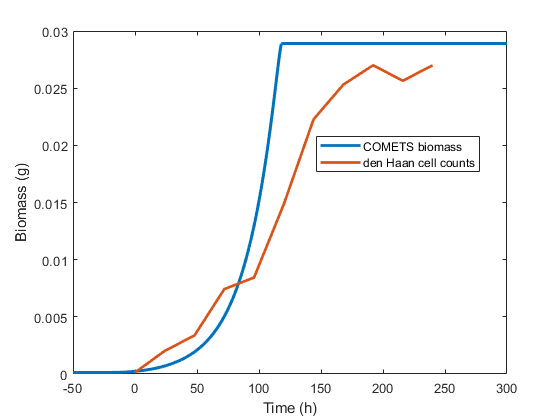



%Denhaan biomass extrapolated from cell counts & max observed biomass reported as .27 g/L
%plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,row.t{1},polyval(pf,row.t{1},S),'lineWidth', 2)
%leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
plot(t_shifted,bio_extend,data.ctdat,data.gdw,'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
%title('Growth')
xlabel('Time (h)')
ylabel('Biomass (g)')
xlim([xmin xmax]);

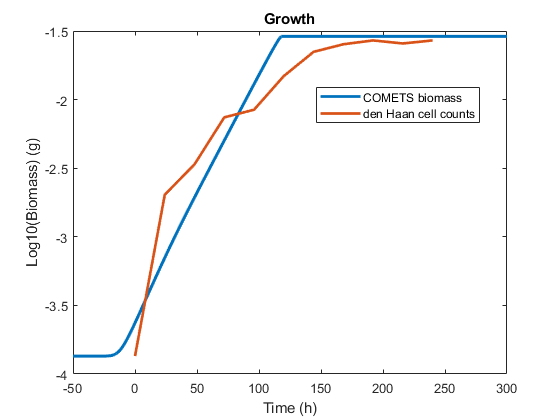


plot(t_shifted,log10(bio_extend),data.ctdat,log10(data.gdw),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
title('Growth')
xlabel('Time (h)')
ylabel('Log10(Biomass) (g)')
xlim([xmin xmax]);

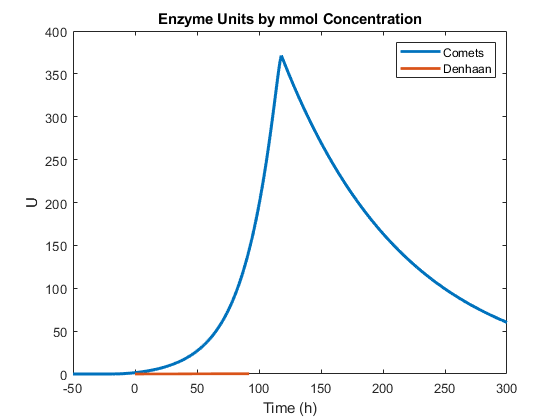

%Compare enzyme activity

%Convert units in in-vivo data to mmol
%NOTE: I SHOULD DO THIS THE OTHER WAY- CONVERT MMOL TO U
% ivdmmol = arrayfun(@(x) units2mmol(x,v.kcat_cel,v.km_cel,v.initcellulose),ivd.denhaan.units);
% plot(row.t{1},row.enzyme_amt{1},ivd.denhaan.units_t,ivdmmol);
v.spaceWidth = 100^(1/3);

xmin = -50;
xmax = 300;
t_extend = [(xmin:-1)'; row.t{1}];
t_shifted = t_extend + row.shift_hours;
simunits = arrayfun(@(x) mmol2units(x,row.kcat_cel(1),row.km_cel(1),args.p2.v.initcellulose),row.enzyme_amt{1});
simunits = [zeros(-xmin,1); simunits];
simdelta = arrayfun(@(x) v2units(x,args.p2.v.timestep),row.cellulose_delta{1} * args.p2.v.glcpercellulose);
simdelta = [zeros(-xmin,1); simdelta];
enzyme_shifted = [zeros(-xmin,1); row.enzyme_amt{1}];
%simunits2 = arrayfun(@(x,y) mmol2units(x,v.kcat_cel,v.km_cel,y),row.enzyme_amt{1},row.cellulose_amt{1});
plot(t_shifted,simunits,ivd.denhaan.units_t,ivd.denhaan.units,'lineWidth', 2);
title('Enzyme Units by mmol Concentration')
xlabel('Time (h)')
ylabel('U')
legend({'Comets', 'Denhaan'})
xlim([xmin xmax]);

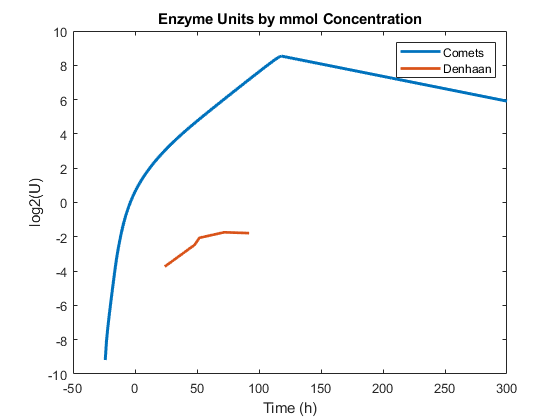


plot(t_shifted,log2(simunits),ivd.denhaan.units_t,log2(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by mmol Concentration')
xlabel('Time (h)')
ylabel('log2(U)')
legend({'Comets', 'Denhaan'})
xlim([xmin xmax]);

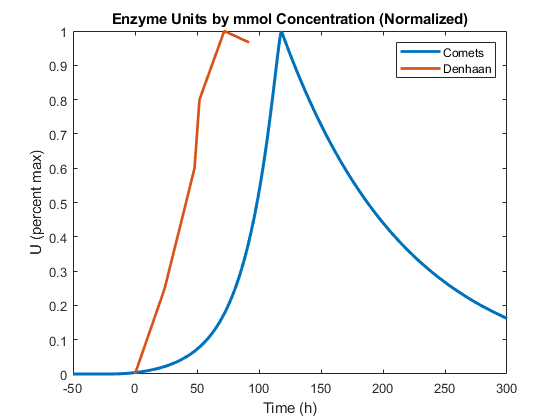


plot(t_shifted,simunits/max(simunits),ivd.denhaan.units_t,ivd.denhaan.units/max(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by mmol Concentration (Normalized)')
xlabel('Time (h)')
ylabel('U (percent max)')
legend({'Comets', 'Denhaan'})
xlim([xmin xmax]);

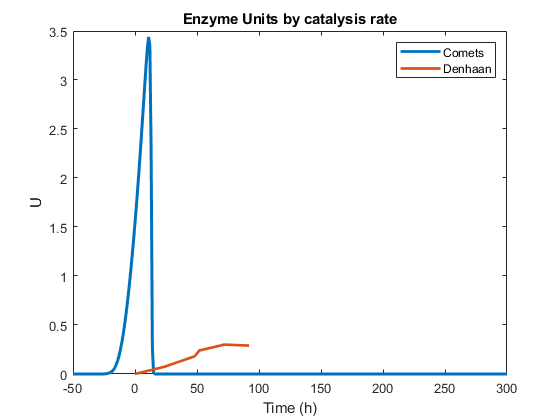



plot(t_shifted(2:end),simdelta,ivd.denhaan.units_t,ivd.denhaan.units,'lineWidth', 2);
title('Enzyme Units by catalysis rate')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('U')
xlim([xmin xmax]);

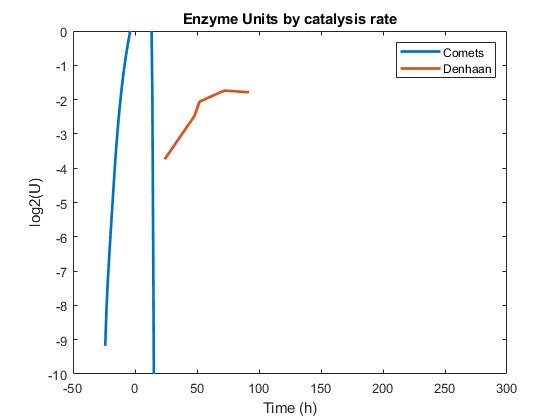


plot(t_shifted(2:end),log2(simdelta),ivd.denhaan.units_t,log2(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by catalysis rate')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('log2(U)')
ylim([-10,0]);
xlim([xmin xmax]);

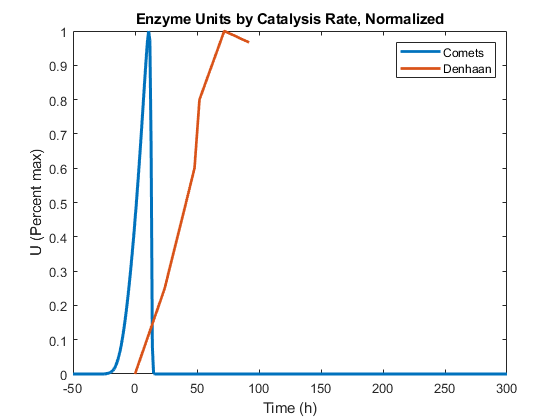


plot(t_shifted(2:end),simdelta / max(simdelta),ivd.denhaan.units_t,ivd.denhaan.units/max(ivd.denhaan.units),'lineWidth', 2);
title('Enzyme Units by Catalysis Rate, Normalized')
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('U (Percent max)')
xlim([xmin xmax]);

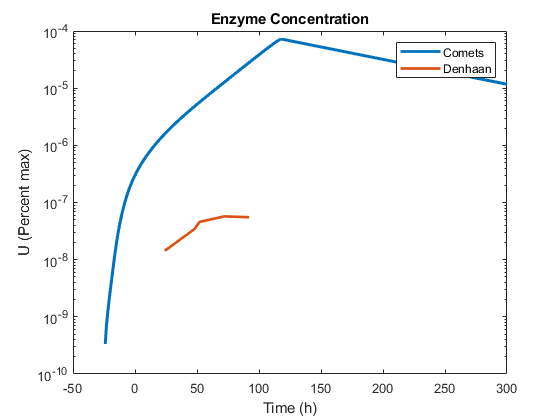


%back-calculates enzyme concentration in Denhaan experiment using the
%kinetic params of the best fit
denhaan_enzyme_amt = arrayfun(@(x) units2mmol(x,row.kcat_cel(1),row.km_cel(1),.5),ivd.denhaan.units);
plot(t_shifted,enzyme_shifted,ivd.denhaan.units_t,denhaan_enzyme_amt,'lineWidth', 2);
title('Enzyme Concentration');
legend({'Comets', 'Denhaan'})
xlabel('Time (h)')
ylabel('U (Percent max)')
set(gca,'Yscale','log')
xlim([xmin xmax]);

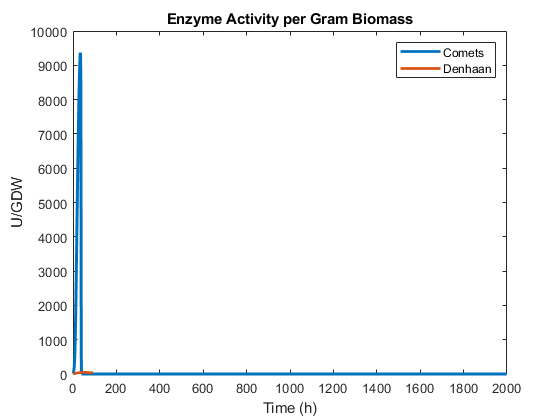

%enzyme activity/biomass over time
c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),c_act_perbio,([0 24 48 72 92]),d_act_perbio,'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('U/GDW')
title('Enzyme Activity per Gram Biomass')

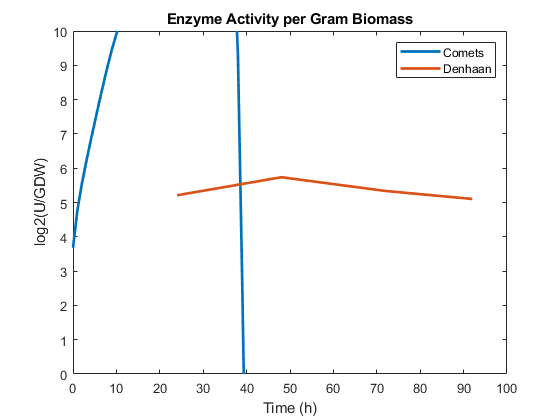


c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),log2(c_act_perbio),([0 24 48 72 92]),log2(d_act_perbio),'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('log2(U/GDW)')
ylim([0,10]);
title('Enzyme Activity per Gram Biomass')

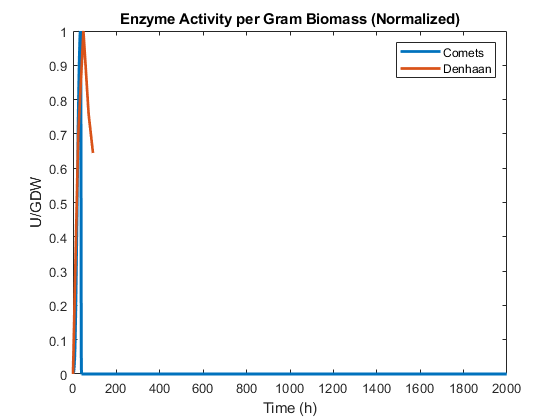


c_act_perbio = (arrayfun(@(x) v2units(x,v.timestep),row.cellulose_delta{1} * v.glcpercellulose) ) ./ row.biomass{1}(1:end-1);
d_act_perbio = [0 (data.units([2 3 5 6]) ./ data.gdw(2:5))];
plot(row.t{1}(1:end-1),c_act_perbio/max(c_act_perbio),([0 24 48 72 92]),d_act_perbio/max(d_act_perbio),'lineWidth',2);
legend({'Comets' 'Denhaan'})
xlabel('Time (h)')
ylabel('U/GDW')
title('Enzyme Activity per Gram Biomass (Normalized)')

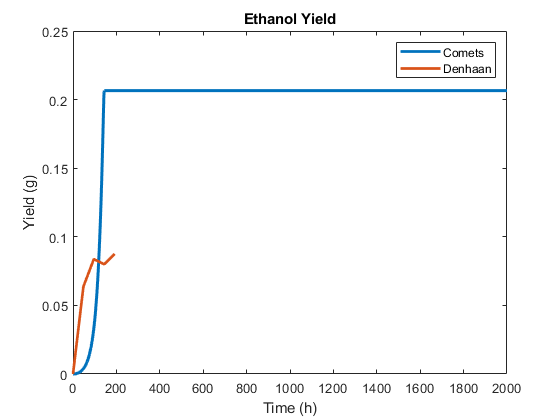

%ethanol
etohcon = row.etoh_amt{1};
etohweight = etohcon * .04607; %46.07g/mole = .04607 grams per millimole
plot(row.t{1},etohweight,data.eptdat,data.etohdat,'lineWidth',2)
legend({'Comets', 'Denhaan'})
title('Ethanol Yield')
xlabel('Time (h)')
ylabel('Yield (g)')

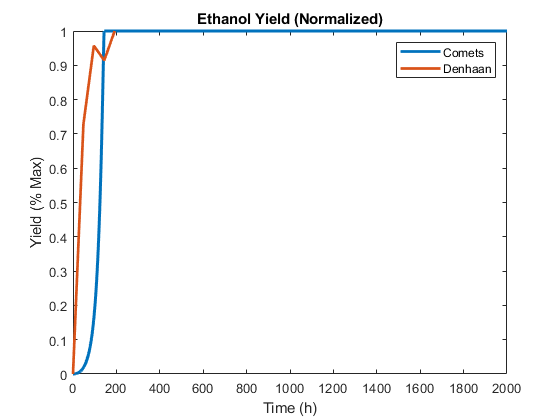


plot(row.t{1},etohweight/max(etohweight),data.eptdat,data.etohdat/max(data.etohdat),'lineWidth',2)
legend({'Comets', 'Denhaan'})
title('Ethanol Yield (Normalized)')
xlabel('Time (h)')
ylabel('Yield (% Max)')

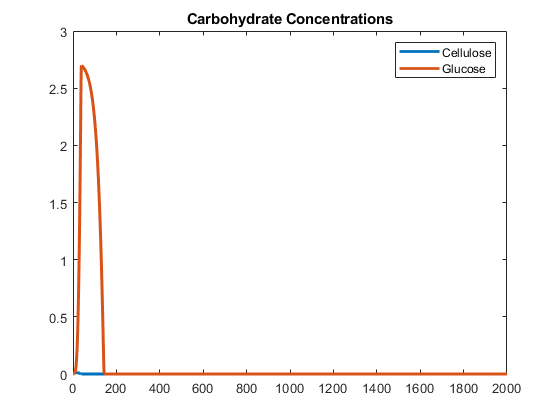


plot(row.t{1},row.cellulose_amt{1},row.t{1},row.glc_amt{1},'LineWidth',2);
legend({'Cellulose' 'Glucose'});
title('Carbohydrate Concentrations');

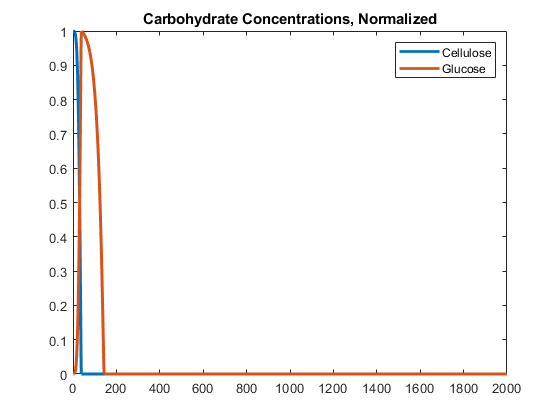


plot(row.t{1},row.cellulose_amt{1}/max(row.cellulose_amt{1}),row.t{1},row.glc_amt{1}/max(row.glc_amt{1}),'LineWidth',2);
legend({'Cellulose' 'Glucose'});
title('Carbohydrate Concentrations, Normalized');

**%Plot data for varying kinetics**

%data prep
dat2_kin = dat2;
dat2_kin.max_biomass = cellfun(@(x) max(x),dat2_kin.biomass);
rmse = dat2_kin.rmse;
% [nrows, ncols] = size(dat2_kin);
% for i = 1:nrows
%     row = dat2_kin(i,:);
%     t_end = find(row.t{1} >= 250,1);
%     bio = row.biomass{1}(1:t_end);
%     t = row.t{1}(1:t_end);
%     y_calc = bio\t;
%     [pf,S] = polyfit(t,bio,3);
%     [y_fit,delta] = polyval(pf,ivd.denhaan.ctdat,S);
% %     hold on;
% %     plot(t,bio,t,y_fit);
% %     plot(t,y_fit+2*delta,'m--',t,y_fit-2*delta,'m--');
% %     hold off;
%     gdw = ivd.denhaan.gdw;
%     res = ivd.denhaan.gdw - polyval(pf,ivd.denhaan.ctdat);
%     %plot(res)
%     r2 = 1 - sum((gdw - y_fit).^2)/sum((gdw - mean(y_fit)).^2);
%     dat2_kin.rs(i) = r2;
%     dat2_kin.ssrs(i) = sum((gdw - y_fit).^2);
% end
% 
% rss_fun3_n = zeros(nrows,1);
% rss_fun4_n = zeros(nrows,1);
% rss_fun3_l = zeros(nrows,1);
% rss_fun4_l = zeros(nrows,1);
% r2_3_n = zeros(nrows,1);
% r2_4_n = zeros(nrows,1);
% r2_3_l = zeros(nrows,1);
% r2_4_l = zeros(nrows,1);
% v3n = zeros(nrows,1);
% v4n = zeros(nrows,1);
% v3l = zeros(nrows,1);
% v4l = zeros(nrows,1);
% k3n = zeros(nrows,1);
% k4n = zeros(nrows,1);
% k3l = zeros(nrows,1);
% k4l = zeros(nrows,1);
% rmse3n = zeros(nrows,1);
% rmse4n = zeros(nrows,1);
% rmse3l = zeros(nrows,1);
% rmse4l = zeros(nrows,1);
% rmse = zeros(nrows,1); %raw RMSE without a regression line
% for i = 1:nrows
%     [rss_fun3_n(i),r2_3_n(i),v3n(i),k3n(i),rmse3n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},3);
%     [rss_fun4_n(i),r2_4_n(i),v4n(i),k4n(i),rmse4n(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},4);
%     [rss_fun3_l(i),r2_3_l(i),v3l(i),k3l(i),rmse3l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},3,'log10');
%     [rss_fun4_l(i),r2_4_l(i),v4l(i),k4l(i),rmse4l(i)] = findFitQuality(ivd.denhaan.ctdat,ivd.denhaan.gdw,dat2_kin.t{i},dat2_kin.biomass{i},4,'log10');
% end
% for i = 1:nrows
%     t_exp = ivd.denhaan.ctdat;
%     b_exp = ivd.denhaan.gdw;
%     t_sim = dat2_kin.t{i};
%     b_sim = dat2_kin.biomass{i};
%     b_sim = b_sim(ismember(t_sim,t_exp));
%     logbexp = log10(b_exp);
%     logbsim = log10(b_sim);
%     summation = 0;
%     n = length(logbexp);
%     for j = 1:n
%         val = logbsim(j) - logbexp(j);
%         val = val^2;
%         summation = summation + val;
%     end
%     rmse(i) = sqrt(summation/n);
% end
% 
% 

% km = dat2_kin.km_cel;
% kcat = dat2_kin.kcat_cel;
% r2_3_n = abs(r2_3_n);
% r2_4_n = abs(r2_4_n);
% r2_3_l = abs(r2_3_l);
% r2_4_l = abs(r2_4_l);
% rs = dat2_kin.rs;
% ssrs = dat2_kin.ssrs;
% dat2_kin.r2 = r2_3_l;
% dat2_kin.rmse_3_log = rmse3l;
% dat2_kin.rmse_4_log = rmse4l;
% dat2_kin.rmse_3 = rmse3n;
% dat2_kin.rmse_4 = rmse4n;
% dat2_kin.rmse = rmse;
% fittab = table(rmse,rss_fun3_n,rss_fun4_n,rss_fun3_l,rss_fun4_l,r2_3_n,r2_4_n,r2_3_l,r2_4_l,v3n,v4n,v3l,v4l,k3n,k4n,k3l,k4l,rs,ssrs,km,kcat)
% rownums = 1:nrows;
% best = rownums(ssrs==min(ssrs))
% best = rownums(rmse3l==min(rmse3l))
% best = rownums(rmse3n==min(rmse3n))
% best = rownums(rmse==min(rmse))
% isbest = [(rmse==min(rmse)) ((rss_fun3_n==min(rss_fun3_n))) ((rss_fun4_n==min(rss_fun4_n))) ((rss_fun3_l==min(rss_fun3_l))) ((rss_fun4_l==min(rss_fun4_l)))...
%     ((r2_3_n==min(r2_3_n))) (r2_4_n==min(r2_4_n)) (r2_3_l==min(r2_3_l)) (r2_4_l==min(r2_4_l)) (rs==min(rs)) (ssrs==min(ssrs))]
% % bestrowidxs = [find((rss_fun3_n==min(rss_fun3_n))) find((rss_fun4_n==min(rss_fun4_n))) find((rss_fun3_l==min(rss_fun3_l))) find((rss_fun4_l==min(rss_fun4_l)))...
% %     find((r2_3_n==min(r2_3_n))) find(r2_4_n==min(r2_4_n)) find(r2_3_l==min(r2_3_l)) find(r2_4_l==min(r2_4_l)) ]
% % best_arr = rownums(bestrowidxs)
% % plotdata = horzcat(ssrs/max(ssrs),rss_fun3_n/max(rss_fun3_n),rss_fun4_n/max(rss_fun4_n),rss_fun3_l/max(rss_fun3_l)...
% %     ,rss_fun4_l/max(rss_fun4_l),r2_3_n/max(r2_3_n),r2_4_n/max(r2_4_n),r2_3_l/max(r2_3_l),r2_4_l/max(r2_4_l),...
% %     k3n/max(k3n),k4n/max(k4n),k3l/max(k3l),k4l/max(k4l));
% % [X,Y] = meshgrid(km,kcat);
% % surf(X,Y,plotdata);
% % legend({'ssrs','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','k3n','k4n','k3l','k4l'});
% besttable = table(dat2_kin.alpha,km,kcat,isbest(:,1),isbest(:,2),isbest(:,3),isbest(:,4),isbest(:,5),isbest(:,6),isbest(:,7),isbest(:,8),isbest(:,9),isbest(:,10),isbest(:,11));
% besttable.Properties.VariableNames = {'alpha','km','kcat','rmse','rss_fun3_n','rss_fun4_n','rss_fun3_l','rss_fun4_l','r2_3_n','r2_4_n','r2_3_l','r2_4_l','rs','ssrs'}

%keep the best alpha
% bestrow = find(ssrs==min(ssrs))
% bestrow = find(dat2_kin.rs == min(dat2_kin.rs))
% bestrow = find(r2_3_l == min(r2_3_l))
% bestrow = find(rmse3l == min(rmse3l))
% bestrow = find(rmse3n == min(rmse3n))
% bestrow = find(rmse3l == min(rmse3l))
bestrow = find(rmse == min(rmse))

bestrow = 26

bestalpha = dat2_kin.alpha(bestrow(1))

bestalpha = 0.0032

log2(bestalpha)

ans = -8.2884

bestkm_millimolar = dat2_kin.km_cel(bestrow)

bestkm_millimolar = 2.6537e-04

bestkm_mgperml = convertMmolarToMgPerMl(bestkm_millimolar,args.p2.v.glcpercellulose * args.p2.v.mass_glcmonomer)

bestkm_mgperml = 0.0094

log10bestkm = log10(bestkm_millimolar)

log10bestkm = -3.5762

bestkcat = dat2_kin.kcat_cel(bestrow)

bestkcat = 87.5022

log10bestkcat = log10(bestkcat)

log10bestkcat = 1.9420

bestlag = dat2_kin.shift_hours(bestrow(1))

bestlag = -25

dat2_kin_singleA = dat2_kin(dat2_kin.alpha == bestalpha,:);

%remove redundant rows
dat2_kin_singleA = sortrows(dat2_kin_singleA,{'alpha','km_cel','kcat_cel'});
temp = dat2_kin_singleA(1,:);
[nrows,ncols] = size(dat2_kin_singleA);
for i = 2:nrows
    lastrow = temp(end,:);
    nextrow = dat2_kin_singleA(i,:);
    if (nextrow.alpha ~= lastrow.alpha || nextrow.km_cel ~= lastrow.km_cel ||...
            nextrow.kcat_cel ~= lastrow.kcat_cel)
        temp = vertcat(temp,nextrow);
    end
end
dat2_kin_best = temp;

%make a surf plot for R-squared over log change in vmax and km
% bestrow = find(dat2_kin_best.r2 == max(dat2_kin_best.r2))
% bestrow = find(dat2_kin_best.rmse_3_log == min(dat2_kin_best.rmse_3_log))
bestrow = find(dat2_kin_best.rmse == min(dat2_kin_best.rmse))

bestrow = 1

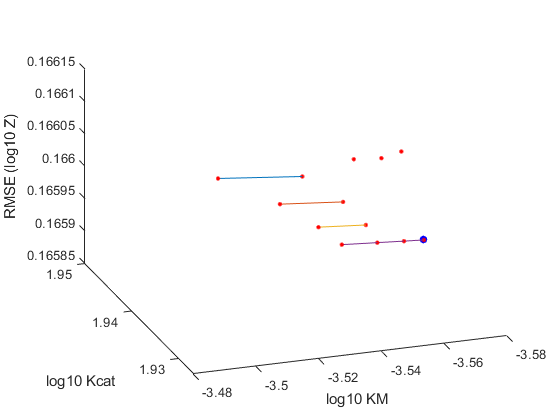

%bestrow = find(dat2_kin_best.rmse_3 == min(dat2_kin_best.rmse_3))
bestrow = bestrow(1);

% %temp fix: ease up on filtering
% dat2_kin_best = dat2_kin;
% bestrow = find(dat2_kin_best.rmse == min(dat2_kin_best.rmse))

km_def = v_default.km_cel;
kcat_def = v_default.kcat_cel;
x = dat2_kin_best.kcat_cel;
x = unique(x);
y = dat2_kin_best.km_cel;
y = unique(y);
z = nan(length(x),length(y));
a = nan(length(x),length(y));
for i = 1:length(x)
    for j = 1:length(y)
        zt = dat2_kin_best(dat2_kin_best.kcat_cel==x(i) & dat2_kin_best.km_cel==y(j),:);
        if (~isempty(zt))
            [nrows,ncols] = size(zt);
            if nrows > 1
                zt = zt(zt.rmse == min(zt.rmse),:);
            end
            z(i,j) = zt.rmse(1);
            a(i,j) = log2(zt.alpha(1));
        end
    end
end
x = log10(x);
y = log10(y);
[X,Y] = meshgrid(x,y);
%surf(X,Y,z');
plot3(X,Y,z');
xlabel('log10 Kcat');
ylabel('log10 KM');
zlabel('RMSE (log10 Z)');

%get colors by alpha


hold on;
plot3(log10(dat2_kin_best.kcat_cel),log10(dat2_kin_best.km_cel),dat2_kin_best.rmse,'.r','markersize',10);
%mark the peak
plot3(log10(dat2_kin_best.kcat_cel(bestrow)),log10(dat2_kin_best.km_cel(bestrow)),dat2_kin_best.rmse(bestrow),'.b','markersize',20);
hold off;

view([251 31])

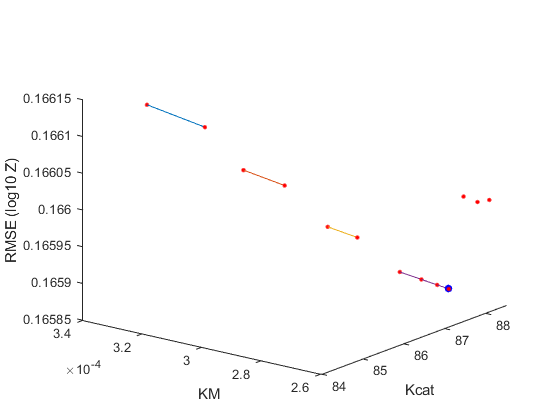



x = dat2_kin_best.kcat_cel;
x = unique(x);
y = dat2_kin_best.km_cel;
y = unique(y);
[X,Y] = meshgrid(x,y);
%surf(X,Y,z');
plot3(X,Y,z');
xlabel('Kcat');
ylabel('KM');
zlabel('RMSE (log10 Z)');
hold on;
plot3((dat2_kin_best.kcat_cel),(dat2_kin_best.km_cel),dat2_kin_best.rmse,'.r','markersize',10);
plot3((dat2_kin_best.kcat_cel(bestrow)),(dat2_kin_best.km_cel(bestrow)),dat2_kin_best.rmse(bestrow),'.b','markersize',20);
hold off;
view([-52 21.600])

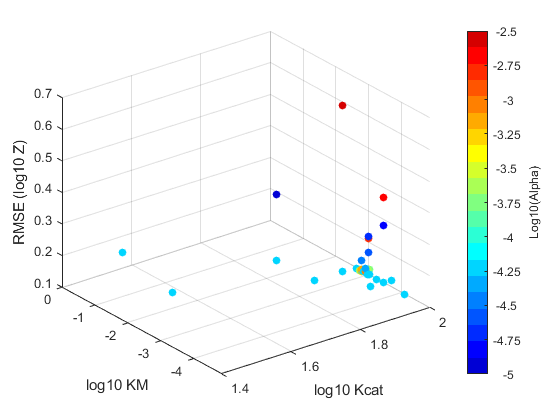

%3d scatter of data at all alphas
x = dat2_kin.kcat_cel;
x = unique(x);
y = dat2_kin.km_cel;
y = unique(y);
z = nan(length(x),length(y));
a = nan(length(x),length(y));
for i = 1:length(x)
    for j = 1:length(y)
        zt = dat2_kin_best(dat2_kin_best.kcat_cel==x(i) & dat2_kin_best.km_cel==y(j),:);
        if (~isempty(zt))
            [nrows,ncols] = size(zt);
            if nrows > 1
                zt = zt(zt.rmse == min(zt.rmse),:);
            end
            z(i,j) = zt.rmse(1);
            a(i,j) = log2(zt.alpha(1));
        end
    end
end
x = log10(x);
y = log10(y);
[X,Y] = meshgrid(x,y);
%surf(X,Y,z');
plot3(X,Y,z');
xlabel('log10 Kcat');
ylabel('log10 KM');
zlabel('RMSE (log10 Z)');

alphas = unique(dat2_kin.alpha);
log10a = log10(alphas);
colors = jet(length(log10a));
colormat = zeros(length(dat2_kin.alpha),3);
for i = 1:length(dat2_kin.alpha)
    colormat(i,:) = colors(logical(dat2_kin.alpha(i)==alphas),:);
end

hold on;
%plot3(log10(dat2_kin.kcat_cel),log10(dat2_kin.km_cel),dat2_kin.rmse,'.','markersize',10);
scatter3(log10(dat2_kin.kcat_cel),log10(dat2_kin.km_cel),dat2_kin.rmse,[],colormat,'filled');
% %mark the peak
% bestrow = find(dat2_kin.rmse==min(dat2_kin.rmse));
% plot3(log10(dat2_kin.kcat_cel(bestrow)),log10(dat2_kin.km_cel(bestrow)),dat2_kin.rmse(bestrow),'.r','markersize',20);
hold off;
colormap(colors);
c = colorbar('eastoutside','TickLabels',num2str((-5:.25:-2.5)'));
c.Label.String = 'Log10(Alpha)';
grid on;

%time series plot of the best fit
data = ivd.denhaan;
bestrow = find(dat2.rmse==min(dat2.rmse));
row = dat2(bestrow(1),:);
besta = row.alpha

besta = 0.0032

bestrmse = min(dat2.rmse)

bestrmse = 0.1659

bestkm_mmolar = row.km_cel

bestkm_mmolar = 2.6537e-04

bestkm_mgperml = convertMmolarToMgPerMl(bestkm_mmolar,args.p2.v.glcpercellulose * args.p2.v.mass_glcmonomer)

bestkm_mgperml = 0.0094

bestkcat = row.kcat_cel

bestkcat = 87.5022

% bestr2 = max(dat2.r2)
% bestrmse_3 = min(dat2.rmse_3)
%v = row.layout{1}.models{1}.v;
[pf,S] = polyfit(row.t{1},row.biomass{1},3);

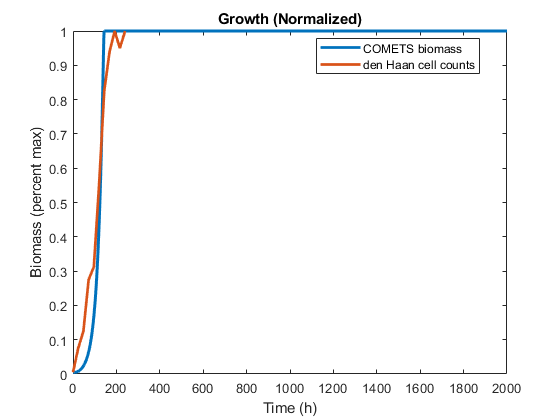


%plot(row.t{1},row.biomass{1}/max(row.biomass{1}),data.ctdat,data.cydat/max(data.cydat),row.t{1},polyval(pf,row.t{1},S)/max(polyval(pf,row.t{1},S)),'lineWidth', 2)
%leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
plot(row.t{1},row.biomass{1}/max(row.biomass{1}),data.ctdat,data.cydat/max(data.cydat),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
title('Growth (Normalized)')
xlabel('Time (h)')
ylabel('Biomass (percent max)')

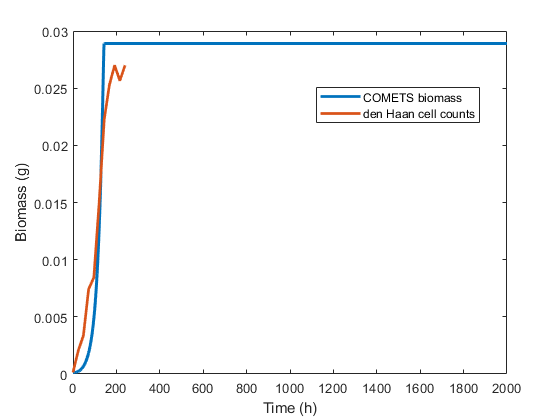



%Denhaan biomass extrapolated from cell counts & max observed biomass reported as .27 g/L
%plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,row.t{1},polyval(pf,row.t{1},S),'lineWidth', 2)
%leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
plot(row.t{1},row.biomass{1},data.ctdat,data.gdw,'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
%title('Growth')
xlabel('Time (h)')
ylabel('Biomass (g)')

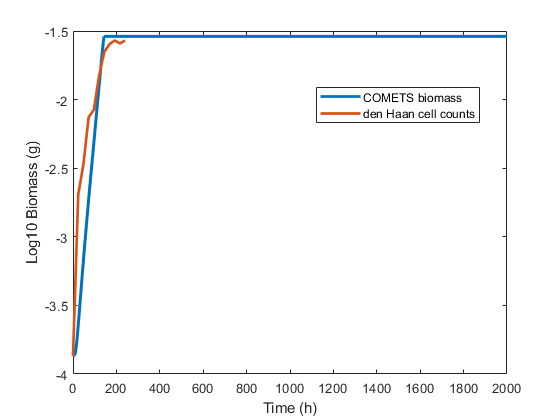


%plot(row.t{1},log10(row.biomass{1}),data.ctdat,log10(data.gdw),row.t{1},log10(polyval(pf,row.t{1},S)),'lineWidth', 2)
%leg = legend({'COMETS biomass' 'den Haan cell counts' 'Best Fit'},'location','best');
plot(row.t{1},log10(row.biomass{1}),data.ctdat,log10(data.gdw),'lineWidth', 2)
leg = legend({'COMETS biomass' 'den Haan cell counts'},'location','best');
%title('Growth')
xlabel('Time (h)')
ylabel('Log10 Biomass (g)')

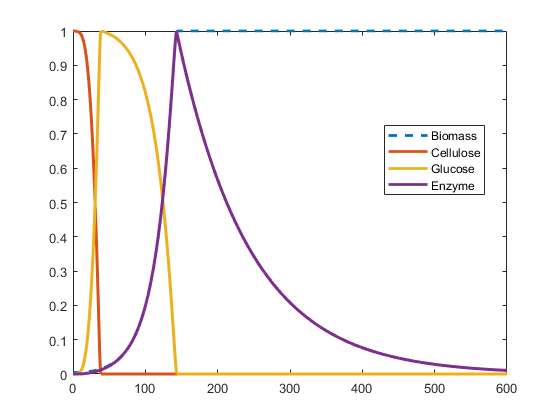

%Basic timeseries for the best run
row = dat2_kin(dat2_kin.rmse == min(dat2_kin.rmse),:);
row = row(1,:);
t = row.t{1};

xmax = 120;
xmax = max(t);
xmax = 600;

glc = row.glc_amt{1};
glc = glc/max(glc);
cel = row.cellulose_amt{1};
cel = cel/max(cel);
bio = row.biomass{1};
bio = bio/max(bio);
enz = row.enzyme_amt{1};
enz = enz/max(enz);
plot(t,bio,'--',t,cel,'-',t,glc,'-',t,enz,'-','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'},'location','best');
xlim([0 xmax]);

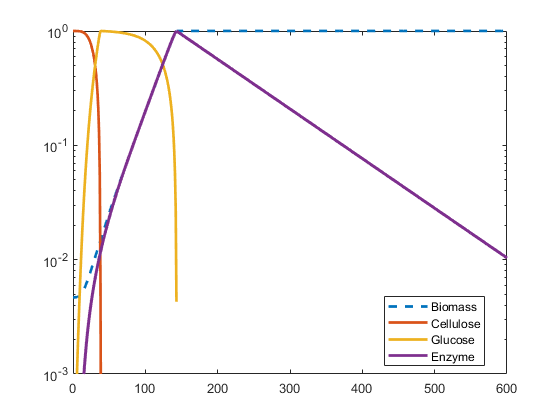


plot(t,bio,'--',t,cel,'-',t,glc,'-',t,enz,'-','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme'},'location','best');
a = gca();
set(a,'YScale','log');
ylim([1e-3,1]);
xlim([0 xmax]);

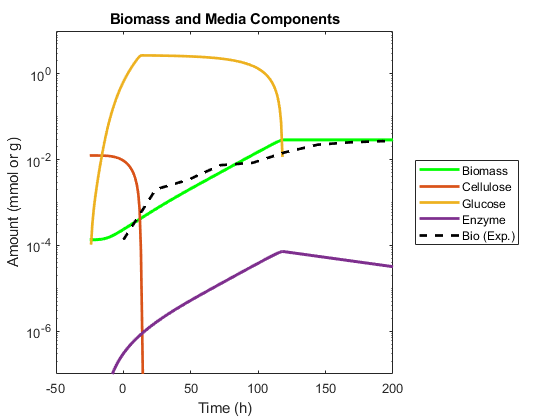


plot(t+row.shift,row.biomass{1},'-g',t+row.shift,row.cellulose_amt{1},'-',t+row.shift,row.glc_amt{1},'-',t+row.shift,row.enzyme_amt{1},'-',ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
legend({'Biomass' 'Cellulose' 'Glucose' 'Enzyme' 'Bio (Exp.)'},'location','eastoutside');
a = gca();
set(a,'YScale','log');
ylim([1e-7,10]);
ylabel('Amount (mmol or g)');
xlabel('Time (h)');
title('Biomass and Media Components')
xlim([-50 200]);


if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\timeseries_media_and_biomass.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\timeseries_media_and_biomass.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\timeseries_media_and_biomass.pdf');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\timeseries_media_and_biomass.eps');%for LaTeX
end


FIGURE 2 FOR PAPER

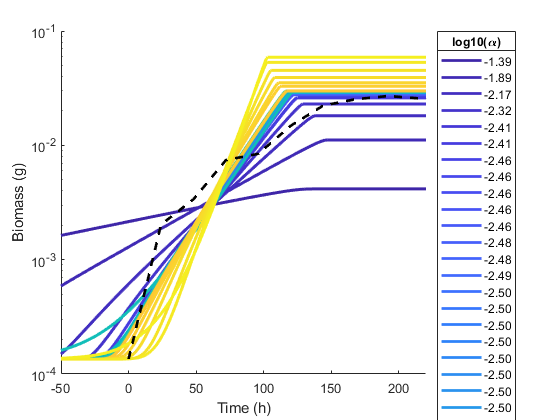

maxtime = 220;

%plot the series adjusted for lag phases
%Version 1: move the sim data

if ~isfield(dat2,'shift_hours')
    steplength = dat2.t{1}(2);
    dat2.shift_hours = dat2.shift * steplength;
end

% %Pare down the data
fig2dat = dat2;
% % 
% % % Attempt 1: get a bunch of alphas around the best A
% % n_pre = 4; %number of values on each side
% % n_post = 4;
% % fig2dat = dat2(bestrow-n_pre:bestrow+n_post,:);
% 
%Attempt 2: manual selection
bestrow = find(dat2.alpha == besta);
%keepas = unique([-1 -1.5 -2 -2.5 -3 -3.5 -4 -4.5 dat2.log10alpha(bestrow)]);
keepas = -1:-.25:-4;
keepas = -1:-.5:-4;
keepas = -.5:-.25:-3;
keepas = dat2.log10alpha;
fig2dat = dat2(ismember(dat2.log10alpha,keepas),:);

f = figure();
hold on;
[nrows,ncols] = size(fig2dat);
colors = parula(2 + nrows);
for i = 1:nrows
    r = fig2dat(i,:);
    steplength = r.t{1}(2);
    t_extend = [(-xmax:steplength:-1)'; r.t{1}];
    t_shifted = t_extend + r.shift_hours;
    bio_extend = [repmat(r.biomass{1}(1),length(t_extend) - length(r.t{1}),1); r.biomass{1}];
    %startpos = find(t_shifted == 0);
    %endpos = find(t_shifted == xmax);
    %plot(t_shifted(startpos:endpos),bio_extend(startpos:endpos),'color',colors(i,:),'lineWidth',2);
    plot(t_shifted,bio_extend,'color',colors(i,:),'lineWidth',2);
end
plot(ivd.denhaan.ctdat,ivd.denhaan.gdw,'--k','linewidth',2);
alphas_log10 = fig2dat.log10alpha;
expphrase = 'Exp.       ';
alphaphrases = num2str(round(alphas_log10,3),'%1.2f');
[~,phrasesize] = size(alphaphrases);
expphrase = expphrase(1:phrasesize);
leg = legend([alphaphrases;expphrase],'location','eastoutside');
title(leg,'log10(\alpha)');
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');
xlim([-50,maxtime]);

%title('Biomass comparison (lag shift:Sim moved to IV)');
hold off;

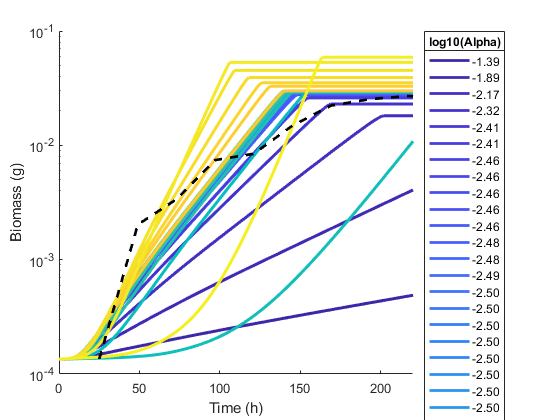


if overwritefiles
    savefig(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\Fig2.fig','compact');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\Fig2.png');
    saveas(f,'C:\sync\biomes\cellulose\optima\data_for_paper\figs\Fig2.eps');%for LaTeX
end



%Version 2: move the experimental data to sit on the best fit
f = figure();
hold on;
[nrows,ncols] = size(fig2dat);
for i = 1:nrows
    r = fig2dat(i,:);
    plot(r.t{1}(1:tmax),r.biomass{1}(1:tmax),'color',colors(i,:),'lineWidth',2);
end
bestshift = fig2dat.shift_hours(fig2dat.rmse == min(fig2dat.rmse));
ctdat_shifted = ivd.denhaan.ctdat - bestshift(1);
plot(ctdat_shifted,ivd.denhaan.gdw,'--k','linewidth',2);
leg = legend([alphaphrases;expphrase],'location','eastoutside');
title(leg,'log10(Alpha)');
xlim([0,maxtime]);
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'YScale','log');

%title('Biomass comparison (lag shift:IV moved to best Sim)');
hold off;

As A Surf Plot without Shifting

s.t = vertcat(dat2.t{1:end});
s.a = arrayfun(@(x) repmat(dat2.log10alpha(x),length(dat2.t{x}),1),1:length(dat2.log10alpha),'uniformoutput',false);
s.a = vertcat(s.a{1:end});
s.bio = vertcat(dat2.biomass{1:end});
[~,x,y,z] = surfArrays(s.t,s.a,s.bio);
cmap = parula;
colormap(cmap(1:210,:));
figure();
%p = surf(x,y,z,y(end:-1:1,:));
p = surf(x,y,z,log10(z));
p.EdgeColor = 'none';
p.FaceColor = 'interp';
%p.FaceAlpha = 0.8;
set(gca,'Zscale','log');
xlabel('Time (h)');
ylabel('Log10(\alpha)');
zlabel('Bioamss (g)');

%add some lines back in
hold on
%Y lines
for i = 1:length(dat2.log10alpha)
    row = dat2(i,:);
    avec = repmat(row.log10alpha(1),size(row.t{1}));
    plot3(row.t{1},avec,row.biomass{1},'-k');
end
%X lines
for i = 1:50:length(dat2.t{1})
    zz = zeros(size(dat2.biomass));
    for j = 1:length(zz)
        b = dat2.biomass{j};
        zz(j) = b(i);
    end
    tvec = repmat(i,size(unique(dat2.log10alpha)));
    plot3(tvec,dat2.log10alpha,zz,'-k');
end

hold off;

ylim([-5,0]);
xlim([0,360]);
set(gca,'YDir','reverse');

view([-67.6903 20.0550]);


As a surf plot with shifting

[nrows,ncols] = size(dat2);
s.t = [];
t_shifted = {};
for i = 1:nrows
    s.t = vertcat(s.t, (dat2.t{i} + dat2.shift_hours(i)));
    t_shifted = [t_shifted {(dat2.t{i} + dat2.shift_hours(i))}];
end

s.a = arrayfun(@(x) repmat(dat2.log10alpha(x),length(dat2.t{x}),1),1:length(dat2.log10alpha),'uniformoutput',false);
s.a = vertcat(s.a{1:end});
s.bio = vertcat(dat2.biomass{1:end});
[~,x,y,z] = surfArrays(s.t,s.a,s.bio);
cmap = parula;
colormap(cmap(1:210,:));
figure();
%p = surf(x,y,z,y(end:-1:1,:));
p = surf(x,y,z,log10(z));
p.EdgeColor = 'none';
p.FaceColor = 'interp';
%p.FaceAlpha = 0.8;
set(gca,'Zscale','log');
xlabel('Time (h)');
ylabel('Log10(\alpha)');
zlabel('Bioamss (g)');

%add some lines back in
hold on
%Y lines
for i = 1:length(dat2.log10alpha)
    row = dat2(i,:);
    avec = repmat(row.log10alpha(1),size(row.t{1}));
    plot3(t_shifted{i},avec,row.biomass{1},'-k');
end
%X lines
for i = -50:50:250
    zz = zeros(size(dat2.biomass));
    for j = 1:length(zz)
        targettime = t_shifted{j} == i;
        b = dat2.biomass{j};
        if any(targettime)
            zz(j) = b(targettime);
        end
    end
    tvec = repmat(i,size(unique(dat2.log10alpha)));
    plot3(tvec,dat2.log10alpha,zz,'-k');
end

hold off;

ylim([-5,0]);
xlim([-50,240]);
set(gca,'YDir','reverse');

view([-55.6142 22.8964]);